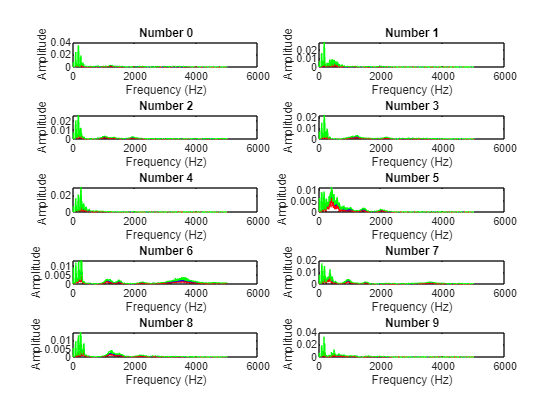

%Exercício 5

freqN = 5000;
amplitudes = getDataMatrix('0', freqN);
freq = (0:freqN-1);

figure;
for i=0:9

    %Calcula mediana
    medians = median(amplitudes, 1);


    % The result is a 1xfreqNx10 matrix. To reshape it into a freqNx10 matrix:
    medians = squeeze(medians);

    % Calculate the first and third quartile for each frequency
    first_quartile = quantile(amplitudes(:,:,i+1), 0.25, 1);
    third_quartile = quantile(amplitudes(:,:,i+1), 0.75, 1);

    % Remove singleton dimensions
    first_quartile = squeeze(first_quartile);
    third_quartile = squeeze(third_quartile);

    %Plot
    subplot(5, 2, i+1);
    plot(freq, medians(:,i+1), 'b');
    hold on;
    plot(freq, first_quartile, 'r');
    plot(freq, third_quartile, 'g');
    hold off;
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    title(sprintf('Number %d', i));
end

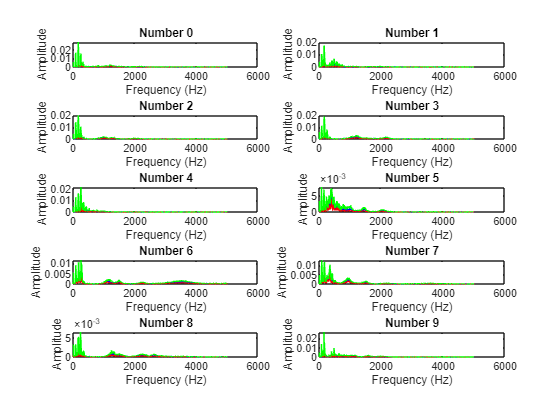

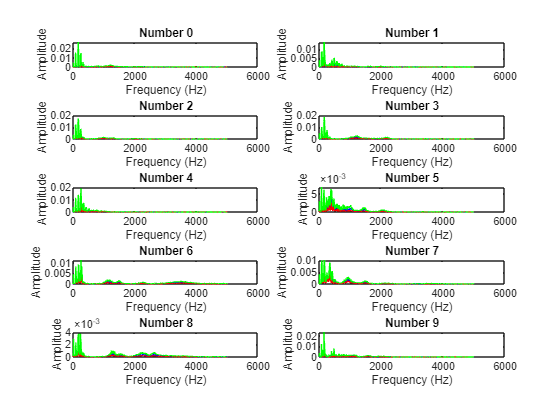



%Exercício 6
windowTypes = {'hamming','blackman','rect'};
for k = 1:length(windowTypes)

    windowType = windowTypes{k};           
    amplitudes = getDataMatrix(windowType,freqN);
    figure;
    for i=0:9

        %Calcula mediana
        medians = median(amplitudes, 1);


        % The result is a 1xfreqNx10 matrix. To reshape it into a freqNx10 matrix:
        medians = squeeze(medians);

        % Calculate the first and third quartile for each frequency
        first_quartile = quantile(amplitudes(:,:,i+1), 0.25, 1);
        third_quartile = quantile(amplitudes(:,:,i+1), 0.75, 1);

        % Remove singleton dimensions
        first_quartile = squeeze(first_quartile);
        third_quartile = squeeze(third_quartile);

        %Plot
        subplot(5, 2, i+1);
        plot(freq, medians(:,i+1), 'b');
        hold on;
        plot(freq, first_quartile, 'r');
        plot(freq, third_quartile, 'g');
        hold off;
        xlabel('Frequency (Hz)');
        ylabel('Amplitude');
        title(sprintf('Number %d', i));
    end
end

ans = logical
   0


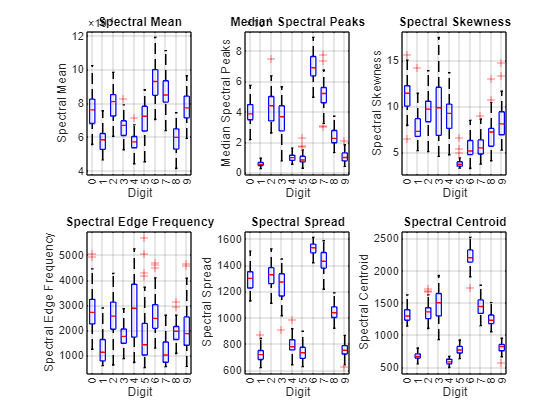


%Exercício 7

% Get the Matrix with the frequencies
    amplitudes = getDataMatrix('0',freqN);
    freq = (0:freqN-1);
% Initialize the vectors
    medianPeaks = zeros(50, 10);
    skewnessMatrix = zeros(50,10);
    edgeFreq = zeros(50,10);
    spectralSpread = zeros(50,10);
    spectralCentroid = zeros(50,10);

% Calculate the features 
    
    % Mean amplitude
        amplitudeMeans = squeeze(mean(amplitudes, 2)); % calculate the means of the freqN values for each audio, get a matrix 50x10

    % All the other features go through the nested loop
        for i = 1:50  
            for j = 1:10  
                medianPeaks(i, j) = median_peaks(amplitudes(i, :, j));      % Median Spectral Peaks      
                skewnessMatrix(i, j) = spectral_skewness(amplitudes(i, :, j));      %Spectral Skewness   
                edgeFreq(i, j) = spectral_edge_frequency(amplitudes(i, :, j), 44100, 0.9);      %Spectral Edge Frequency 
                spectralSpread(i, j) = spectral_spread(amplitudes(i, :, j), freq);      %Spectral Spread
                spectralCentroid(i,j) = sum(freq .* abs(amplitudes(i,:,j))) / sum(abs(amplitudes(i,:,j)));      %Spectral Centroid
            end
        end



matrices = {amplitudeMeans,medianPeaks,skewnessMatrix, edgeFreq,spectralSpread, spectralCentroid};
labels = {"Spectral Mean","Median Spectral Peaks", "Spectral Skewness", "Spectral Edge Frequency", "Spectral Spread", "Spectral Centroid"};

%Plot the features using boxplot
plotBoxplots(matrices,labels);

ans = logical
   0


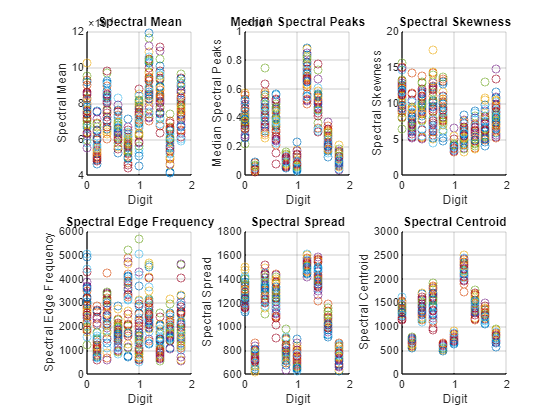

plotScatterplots(matrices,labels);

% adicionar plot3d !!! no 3 tambem